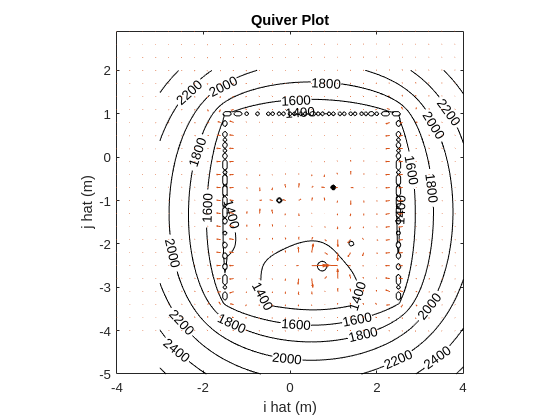

hold on;
[x,y]=meshgrid(-3:0.05:4,-5:0.05:2);

barrel = log(sqrt((x-0.75).^2+(y+2.5).^2));

box_1 = log(sqrt((x-1.41).^2+(y+2).^2));
box_2 = log(sqrt((x-1).^2+(y+0.7).^2));
box_3 = log(sqrt((x+0.25).^2+(y+1).^2));

% Left Wall
left_wall = 0;

for a = -1.5:0.01:2.5
    left_wall = left_wall - log(sqrt((x-a).^2 + (y+3.37).^2));
end

% Right Wall
right_wall = 0;

for a = -1.5:0.01:2.5
    right_wall = right_wall - log(sqrt((x-a).^2 + (y-1).^2));
end

% Top Wall
top_wall = 0;

for a = -3.37:0.01:1
    top_wall = top_wall - log(sqrt((x+1.5).^2 + (y-a).^2));
end

% Bottom Wall
bottom_wall = 0;

for a = -3.37:0.01:1
    bottom_wall = bottom_wall - log(sqrt((x-2.5).^2 + (y-a).^2));
end

%v = barrel - box_1 - box_2 - box_3 - left_wall - right_wall - top_wall - bottom_wall
v = 100*barrel - 70*box_1 - 40*box_2 - 50*box_3 - left_wall - right_wall - top_wall - bottom_wall;

contour(x,y,v,'k','ShowText','On')
axis equal
[x,y]=meshgrid(-4:0.3:4,-4:0.3:3);


% X
barrel_x = (x-0.75)./((x-0.75).^2+(y+2.5).^2);

box_1_x = (x-1.41)./((x-1.41).^2+(y+2).^2);
box_2_x = (x-1)./((x-1).^2+(y+0.7).^2);
box_3_x = (x+0.25)./((x+0.25).^2+(y+1).^2);

% Left Wall X
left_wall_x = 0;

for a = -1.5:0.01:2.5
    left_wall_x = left_wall_x - (x-a)./((x-a).^2+(y+3.37).^2);
end

% Right Wall X
right_wall_x = 0;

for a = -1.5:0.01:2.5
    right_wall_x = right_wall_x - (x-a)./((x-a).^2+(y-1).^2);
end

% Top Wall X
top_wall_x = 0;

for a = -3.37:0.01:1
    top_wall_x = top_wall_x - (x+1.5)./((x+1.5).^2+(y-a).^2);
end

% Bottom Wall X
bottom_wall_x = 0;

for a = -3.37:0.01:1
    bottom_wall_x = bottom_wall_x - (x-2.5)./((x-2.5).^2+(y-a).^2);
end

fx = 100*barrel_x - 70*box_1_x - 40*box_2_x - 50*box_3_x + left_wall_x + right_wall_x + top_wall_x + bottom_wall_x;

% Y
barrel_y = (y+2.5)./((x-0.75).^2+(y+2.5).^2);

box_1_y = (y+2)./((x-1.41).^2+(y+2).^2);
box_2_y = (y+0.7)./((x-1).^2+(y+0.7).^2);
box_3_y = (y+1)./((x+0.25).^2+(y+1).^2);

% Left Wall Y
left_wall_y = 0;

for a = -1.5:0.01:2.5
    left_wall_y = left_wall_y - (y+3.37)./((x-a).^2+(y+3.37).^2);
end

% Right Wall Y
right_wall_y = 0;

for a = -1.5:0.01:2.5
    right_wall_y = right_wall_y - (y-1)./((x-a).^2+(y-1).^2);
end

% Top Wall Y
top_wall_y = 0;

for a = -3.37:0.01:1
    top_wall_y = top_wall_y - (y-a)./((x+1.5).^2+(y-a).^2);
end

% Bottom Wall Y
bottom_wall_y = 0;

for a = -3.37:0.01:1
    bottom_wall_y = bottom_wall_y - (y-a)./((x-2.5).^2+(y-a).^2);
end

fy = 500*barrel_y - 50*box_1_y - 200*box_2_y - 250*box_3_y + left_wall_y + right_wall_y + top_wall_y + bottom_wall_y;

%quiver(x,y,gradient(fx),gradient(fy))
quiver(x,y,gradient(fx),gradient(fy))
title('Quiver Plot')
xlabel('i hat (m)')
ylabel('j hat (m)')

axis equal